# Average Filter

R = 51;
d = randi(50,1,R)/100

d =     0.4900    0.0400    0.3000    0.2100    0.1600    0.1400    0.3800    0.5000    0.1000    0.4000    0.1000    0.5000    0.4100    0.2200    0.3700    0.2500    0.4100    0.1800    0.0400    0.3000    0.4600    0.1000    0.2200    0.3800    0.0200    0.4800    0.3900    0.2800    0.1000    0.2500    0.2600    0.5000    0.4300    0.4900    0.3400    0.2100    0.4700    0.2400    0.1200    0.2000    0.3600    0.2800    0.3800    0.5000    0.4900    0.2700    0.4900    0.0600    0.0300    0.1600


m = 0:R-1;
s = 2*m.*(0.9.^m); % Generate uncorrupted signal
x = s + d; % Generate noise corrupted signal
b=ones(5,1)/5;
a=1;
y= filter(b,a,x);
h=b

h =     0.2000
    0.2000
    0.2000
    0.2000
    0.2000


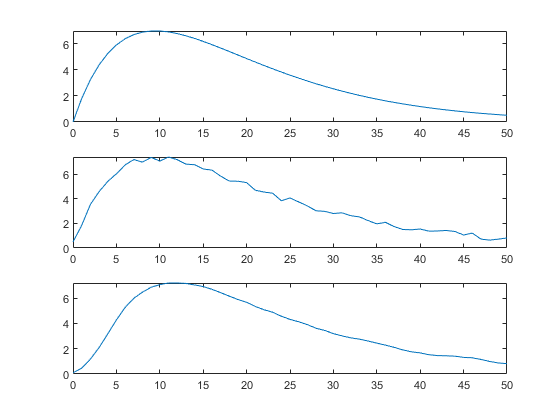

yc=conv(b,x);
subplot(3,1,1);plot(m,s);
subplot(3,1,2);plot(m,x);
subplot(3,1,3);plot(m,y);

length(yc)

ans = 55

R = 51;
d = randi(50,1,R)/100

d =     0.4700    0.2000    0.1400    0.0800    0.2000    0.1900    0.0700    0.2200    0.0500    0.3100    0.0100    0.2900    0.4000    0.1200    0.2300    0.2900    0.0400    0.2500    0.3300    0.1200    0.4200    0.4900    0.4300    0.2600    0.1400    0.3800    0.1200    0.4800    0.3200    0.3100    0.0900    0.0500    0.1300    0.4300    0.4600    0.3500    0.3700    0.1200    0.2900    0.4100    0.2100    0.5000    0.0500    0.1700    0.2600    0.0400    0.3700    0.2800    0.2700    0.4200


m = 0:R-1;
s = 2*m.*(0.9.^m); % Generate uncorrupted signal
x = s + d; % Generate noise corrupted signal
b=ones(5,1)/5;
a=1;
y= filter(b,a,x);
h=b

h =     0.2000
    0.2000
    0.2000
    0.2000
    0.2000


yc=conv(b,x);

## Real-Life Application: Stock value

load("stock.mat")
whos

  Name        Size              Bytes  Class     Attributes

  R           1x1                   8  double              
  a           1x1                   8  double              
  ans         1x1180             9440  double              
  b          30x1                 240  double              
  d           1x51                408  double              
  h           5x1                  40  double              
  m           1x51                408  double              
  s           1x51                408  double              
  stock       2x1180            18880  double              
  x           1x51                408  double              
  y           1x1180             9440  double              
  yc          1x55                440  double              



plot(stock(1,: ),stock(2,: ),'b');
hold;

Current plot held



b = ones(30,1)/30

b =     0.0333
    0.0333
    0.0333
    0.0333
    0.0333
    0.0333
    0.0333
    0.0333
    0.0333
    0.0333


y=filter(b,1,stock(2,:))

y =     0.7653    1.5317    2.3120    3.1070    3.8797    4.6747    5.4713    6.2747    7.0863    7.8880    8.6767    9.4097   10.1410   10.8677   11.6123   12.3227   13.0233   13.7190   14.4300   15.1173   15.7933   16.4850   17.1590   17.8280   18.5037   19.1673   19.8423   20.5040   21.1657   21.8350   21.7577   21.7027   21.6237   21.5187   21.4500   21.3430   21.2377   21.1093   20.9717   20.8473   20.7317   20.6580   20.5967   20.5353   20.4640   20.4097   20.3607   20.3337   20.3280   20.3513


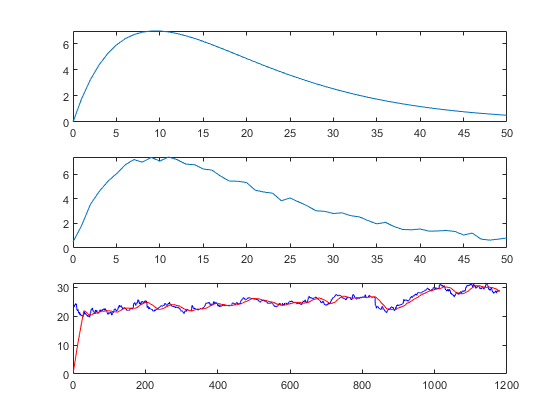

hold on
plot(stock(1,: ),stock(2,: ),'b');
plot(y,'r')
hold off

## LTI Systems

interval=10*(1/300); %  10 ลูกคลื่นของสัญญาณ 300 Hz คิดเป็นช่วงเวลา
time=0:1/6000:interval

time =          0    0.0002    0.0003    0.0005    0.0007    0.0008    0.0010    0.0012    0.0013    0.0015    0.0017    0.0018    0.0020    0.0022    0.0023    0.0025    0.0027    0.0028    0.0030    0.0032    0.0033    0.0035    0.0037    0.0038    0.0040    0.0042    0.0043    0.0045    0.0047    0.0048    0.0050    0.0052    0.0053    0.0055    0.0057    0.0058    0.0060    0.0062    0.0063    0.0065    0.0067    0.0068    0.0070    0.0072    0.0073    0.0075    0.0077    0.0078    0.0080    0.0082


x=5*cos(2*pi*300*time) +7*cos(2*pi*1200*time)

x =    12.0000    6.9184   -1.6180   -2.7242    3.7082    7.0000    0.6180   -8.6020   -9.7082   -2.5922    2.0000   -2.5922   -9.7082   -8.6020    0.6180    7.0000    3.7082   -2.7242   -1.6180    6.9184   12.0000    6.9184   -1.6180   -2.7242    3.7082    7.0000    0.6180   -8.6020   -9.7082   -2.5922    2.0000   -2.5922   -9.7082   -8.6020    0.6180    7.0000    3.7082   -2.7242   -1.6180    6.9184   12.0000    6.9184   -1.6180   -2.7242    3.7082    7.0000    0.6180   -8.6020   -9.7082   -2.5922


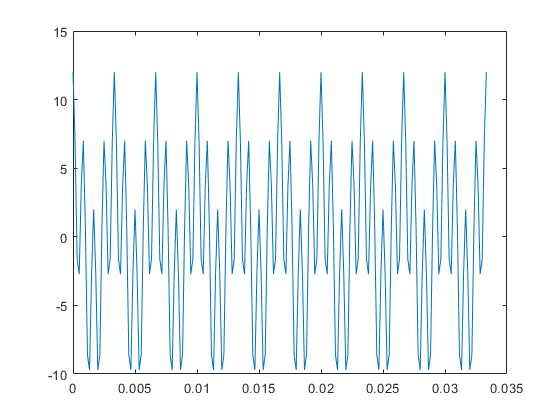

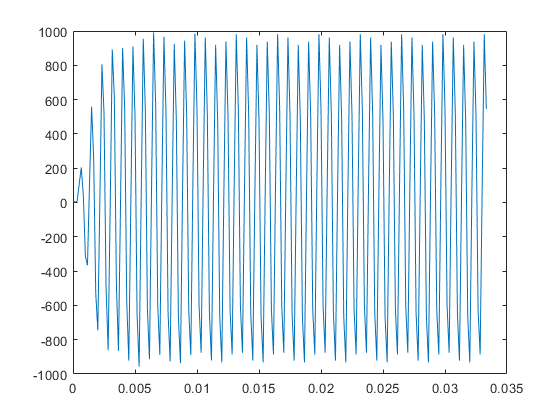

figure;
plot(time,x)

y1=filter([0.692 -1.762 3.925 3.545 -1.762 0.692], [1 -2.238 3.921 -3.844 3.075 -1.367 0.478], x);

figure;
plot(time,y1)

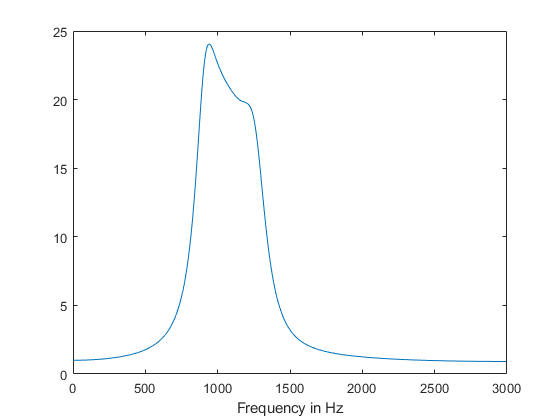

[H W]=freqz([0.692 - 1.762 3.545 -3.925 3.545 -1.762 0.692],[1 -2.238 3.921 -3.844 3.075 -1.367 0.478]);
figure;
plot((W*6000)/(2*pi),abs(H));
xlabel('Frequency in Hz');

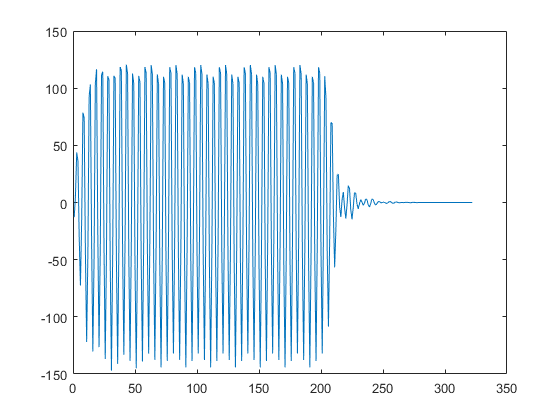

h=impz([0.692 - 1.762 3.545 -3.925 3.545 -1.762 0.692],[1 -2.238 3.921 -3.844 3.075 -1.367 0.478]);
y2=conv(h,x);
figure; plot(y2);

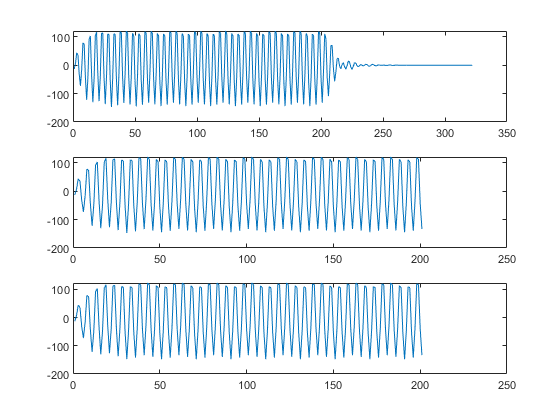

h50=h(1:50);
h32=h(1:32);
y3=filter(h50,1,x); % you can use conv, but remember your output would have more  	%member than member of input
y4=filter(h32,1,x);
figure;
subplot(3,1,1);plot(y2);
subplot(3,1,2);plot(y3);
subplot(3,1,3);plot(y4);

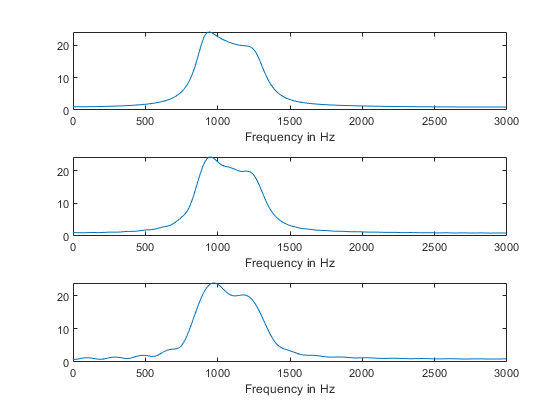

[H50 W]= freqz(h50,1);
[H32 W]= freqz(h32,1);
figure;
subplot(3,1,1); plot((W*6000)/(2*pi),abs(H));xlabel('Frequency in Hz');
subplot(3,1,2); plot((W*6000)/(2*pi),abs(H50));xlabel('Frequency in Hz');
subplot(3,1,3); plot((W*6000)/(2*pi),abs(H32));xlabel('Frequency in Hz');

## Digital Image Filter

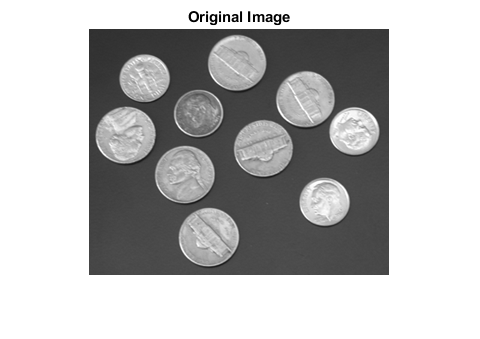

I = imread('coins.png');
I = double(I); % since pixel value in ‘coins.jpg’ is unsigned integer
h = ones(5,5) / 25;
%h = rot90(rot90(h)); % do not need to rotate
I2 = conv2(double(I), double(h)); % 2D-convotion operation needs
                                              %double value to compute
imshow(uint8(I)), title('Original Image'); % Covert back to unsigned integer

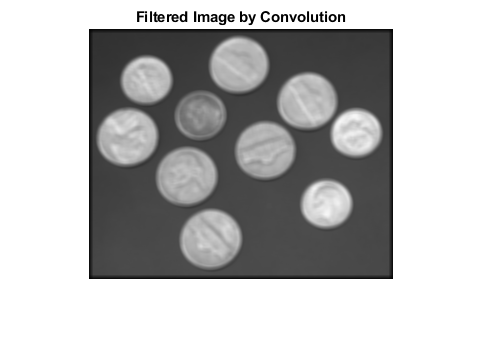

                                                     %before display
figure, imshow(uint8(I2));
title('Filtered Image by Convolution')

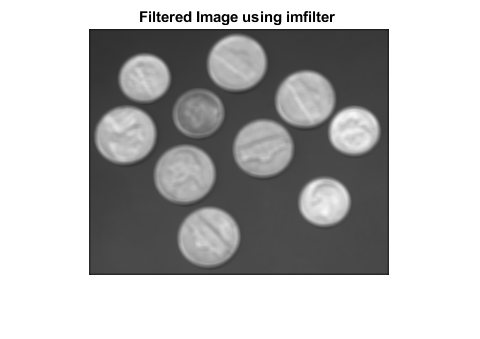

I = imread('coins.png');
I = double(I); % since pixel value in ‘coins.jpg’ is unsigned integer
h = ones(5,5) / 25;
I3 = imfilter(I,h);
figure; imshow(uint8(I3)), title('Filtered Image using imfilter ')